# Tema 11

**Pb 1. **Implementati functii ce genereaza formule de cuadratura gaussiene pentru ponderile clasice date in tabela 1.

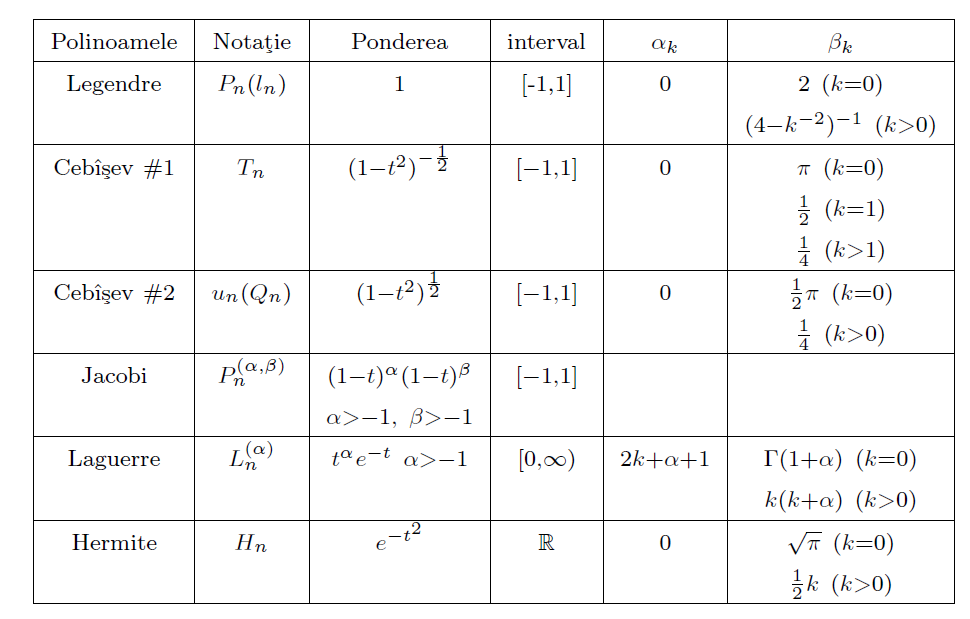

Legendre $\int_{-1}^1 \sin \left(x^2 \right)\mathrm{dx}$

clear
syms x
f=@(x) sin(x .^ 2);
a = -1; b = 1; n = 10;

[g_nodes, g_coeff] = Legendre(n);
legendre_value = vquad(g_nodes, g_coeff, f)

legendre_value = 0.6205

actual_value = quad(f, -1, 1)

actual_value = 0.6205

Cebîșev #1 $\int_{-1}^1 \frac{\cos \left(x\right)}{\sqrt{1-x^2 }}\mathrm{dx}$

clear
syms x
f=@(x) cos(x) / sqrt(1 - x .^ 2);
a = -1; b = 1; n = 10;

[g_nodes, g_coeff] = Cebisev1(n);
cebisev1_value = vquad(g_nodes, g_coeff, @cos)

cebisev1_value = 2.4039

actual_value = double(int(f(x), x, a, b))

actual_value = 2.4039

Cebîșev #2 $\int_{-1}^1 \sqrt{1-x^2 }\cos \left(x\right)\mathrm{dx}$

clear
syms x
f=@(x) sqrt(1 - x .^ 2) / cos(x);
a = -1; b = 1; n = 10;

[g_nodes, g_coeff] = Cebisev2(n);
cebisev2_value = vquad(g_nodes, g_coeff, @cos)

cebisev2_value = 1.3825

actual_value = double(int(f(x), x, a, b))

actual_value = 1.8227

Jacobi $\int_{-1}^1 \sqrt{\frac{1-x}{1+x}}\frac{x^2 }{1+x^2 }\mathrm{dx}$

clear
syms x
g = @(x) x .^ 2 ./ (1 + x .^ 2);
f = @(x) sqrt((1 - x) / (1 + x)) * g(x);
a = -1/2; b = 1/2; n = 8;

[g_nodes, g_coeff] = Jacobi(n, a, b);
jacobi_value = vquad(g_nodes, g_coeff, g)

jacobi_value = 0.9202

actual_value = double(int(f, x, -1, 1))

actual_value = 0.9202

Laguerre $\int_0^{\infty } e^{-x} \;\sin \left(x\right)\mathrm{dx}$

clear
syms x
f=@(x) exp(-x) * sin(x);
a = 0; b = Inf; n = 6;

[g_nodes, g_coeff] = Laguerre(n, a);
laguerre_value = vquad(g_nodes, g_coeff, @sin)

laguerre_value = 0.5000

actual_value = double(int(f(x), x, a, b))

actual_value = 0.5000

Hermite $\int_{-\infty }^{\infty } e^{{-x}^2 } \;\left(\cos \left(x\right)+\sin \left(x\right)\right)\mathrm{dx}$

clear
syms x
f=@(x) cos(x) + sin(x);
a = -Inf; b = Inf; n = 10;

[g_nodes, g_coeff] = Hermite(n);
hermite_value = vquad(g_nodes, g_coeff, f)

hermite_value = 1.3804

actual_value = double(int(exp(- x .^ 2) * f(x), x, a, b))

actual_value = 1.3804